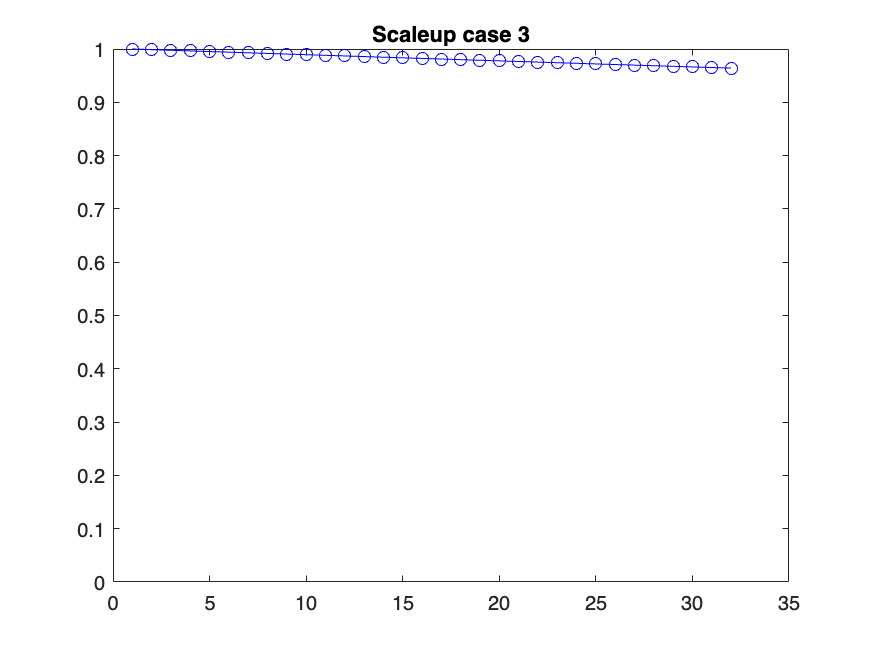

clear all
close all
clc

m=100;
n=5;
k=sqrt(m);
P=1:32;

m1=floor(P*m);
n1=floor(P*n);
k1=floor(k*P);

%for j=1:5
    for i=1:length(P)
    
        numerator=m*(3*n*k+k+n+1)+k*(2+n);
        denumerator=(P(i)*m/P(i))*(3*n*k+k+n+1)+k*(2*P(i)+n);
        
        %denumerator=((m/P(i))*(3*n*k+k+n+1)+k*(2*P(i)+n))*P(i);
        % denumerator(i)=(m1(i)/P(i))*(3*n1(i)*k1(i)+k1(i)+n1(i)+1)+k1(i)*(2*P(i)+n1(i));
        
        %scaleup(j,i)=numerator/denumerator(i);
        scaleup(i)=numerator/denumerator;
    
    end
%end


figure();
%for j=1:5
    plot(P,scaleup,'b-o');
    hold on
    ylim([0,1])
    title('Scaleup case 3');

%end


